# WELCOME TO V768 - Measuring Vision with Psychophysics

Lab 1 - Classical Methods

Learning Outcomes (what you will be able to do at the end):

- Describe three classical psychophysical methods (limits, adjustment, constant stimuli).

- Identify strengths and weaknesses of these methods.

Questions: 

- A.1 - How does the method of limits work? You can use this experiment as an exmple to explain. 

- A.2 - Write a figure caption for the three panels in figure 1 

- A.3 - What are the potential weaknesses of the method of limits? (These can include practical problems with data collection.)

- -----------------------------------------------------------------------------------

- B.1 - How does the method of adjustment work?

- B.2 - Write a figure caption for the panels in figure 2. 

- B.3 - What are the potential weaknesses of the method of adjustment?

- -----------------------------------------------------------------------------------

- C.1 - How does the method of constant stimuli work? You can use this experiment as an example to explain. 

- C.2 - Write a figure caption for the panels in figure 3. 

- C.3 - What are the potential weaknesses of the method of constant stimuli?

- -----------------------------------------------------------------------------------

- D.1 (Wrapup Question): Are these three experiments measuring the same thing? Explain the similarities and differences. Can you change the experiments so that they do measure the same thing?

## A. METHOD OF LIMITS

Instructions: First you will need to collect data. The folder titled "method-of-limits" contains a .psyexp file that you will open using psychopy. Run the experiment -- there are instructions on the first panel for how to do each trial. Use the data generated in that experiment to do the analysis below.

## Load the data --

note: there will be a warning about a 'VariableNamingRule'. This is because psychopy's default naming choices. The changes that matlab makes replaces the '.' (periods) with '_' (underscores) which is totally fine.

% change the filename to the one you generated during data collection
filename = 'method-of-limits/data/demo_method-of-limits_2025-01-06_16h24.27.517.csv';
limit_data = readtable(filename);

% remove the rows/columns associated with the instructions in psychopy
limit_data(1,:)=[];
remove = {'notes','instructions_started','instructions_stopped'};
limit_data(:,remove) = [];

## Visualize the trials

For this experiment, the grayscale luminance range in psychopy was -1 to 1, where -1 is black, 1 is white and 0 is middle gray. The background color was set to 0.

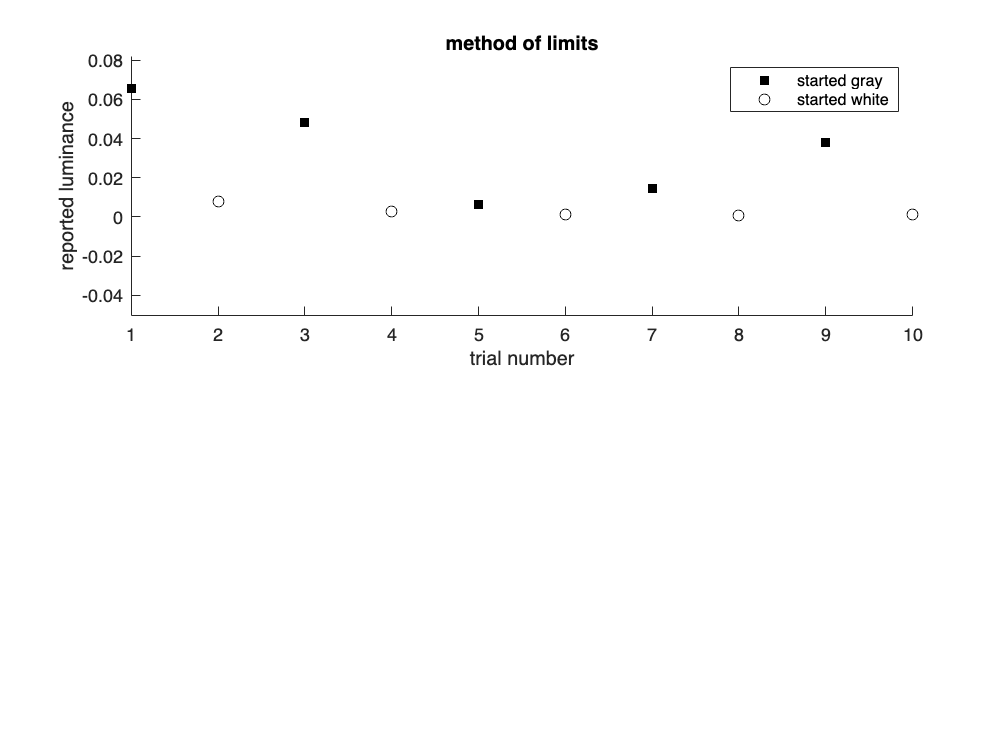

% the variable luminance_response contains the response
luminance_response = limit_data.response;

% the variable direction indicates where the stimulus started, at white (1)
% or background gray (-1)
stimulus_start = limit_data.direction;
trials = 1:size(adjust_data,1);

figure(1); clf; 
subplot(211); hold on;

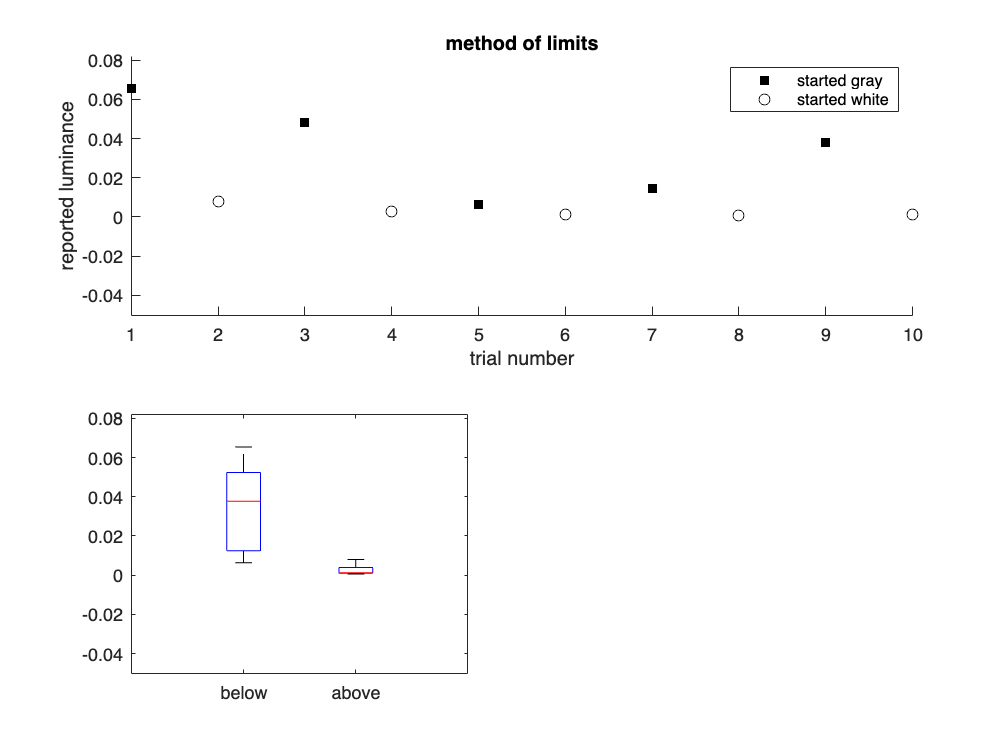


% plot the trials where the response started below
ind = stimulus_start==-1;
plot(trials(ind),luminance_response(ind),'ks','MarkerFaceColor','k')

% plot the trials where the response started below
ind = stimulus_start==1;
plot(trials(ind),luminance_response(ind),'ko')

legend('started gray','started white');
xlabel('trial number');
ylabel('reported luminance');
title('method of limits')
ylim([-.05,1.25*max(luminance_response)])

## Plot the average reported luminance separated by direction of change

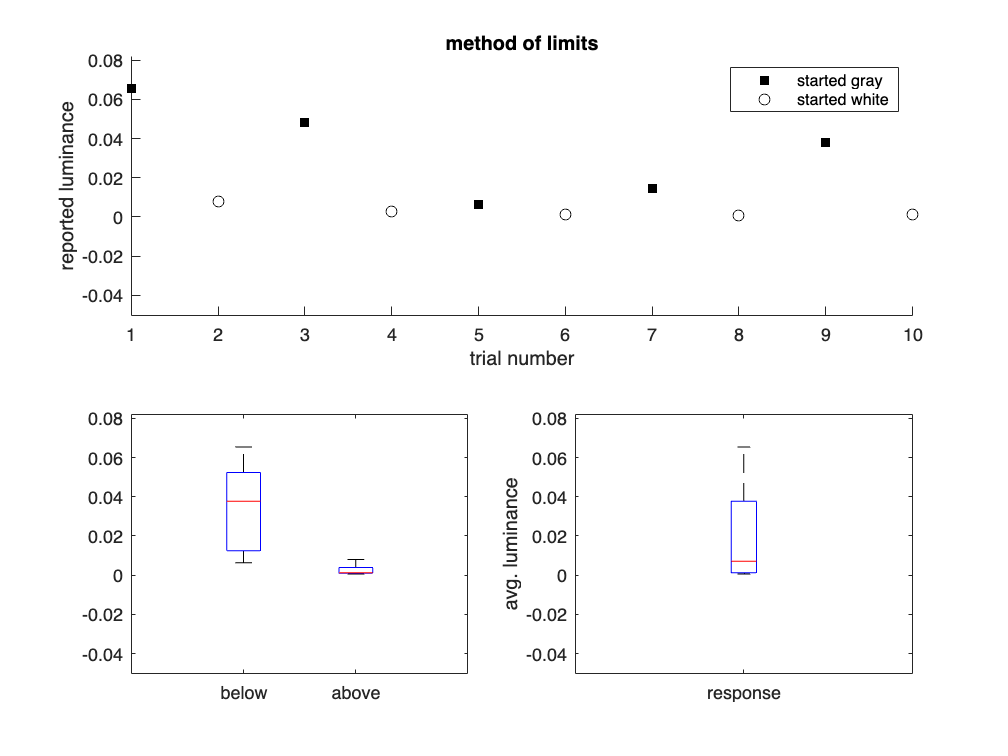

subplot(223); hold on;

boxplot(luminance_response,stimulus_start)
xlim([0,3])
ylim([-.05,1.25*max(luminance_response)])

set(gca,'XTickLabel',{'below','above'})

## Plot the average reported luminance

subplot(224); hold on;
boxplot(luminance_response)
xlim([0,2])
ylim([-.05,1.25*max(luminance_response)])
ylabel('avg. luminance');
set(gca,'XTickLabel',{'response'})

## B. METHOD OF ADJUSTMENT

Instructions: First you will need to collect data. The folder titled "method-of-adjustment" contains a .psyexp file that you will open using psychopy. Run the experiment -- there are instructions on the first panel for how to do each trial. Use the data generated in that experiment to do the analysis below.

## Load the data 

% change the filename to the one you generated during data collection
filename = 'method-of-adjustment/data/demo_method-of-adjustment_2025-01-06_16h30.16.790.csv';
adjust_data = readtable(filename);
% remove the rows/columns associated with the instructions in psychopy
adjust_data(1,:)=[];
remove = {'notes','instructions_started','instructions_stopped'};
adjust_data(:,remove) = [];

## Visualize the trials

For this experiment, the grayscale luminance range in psychopy was -1 to 1, where -1 is black, 1 is white and 0 is middle gray. The background color was set to 0 and the target luminance was set .3679.

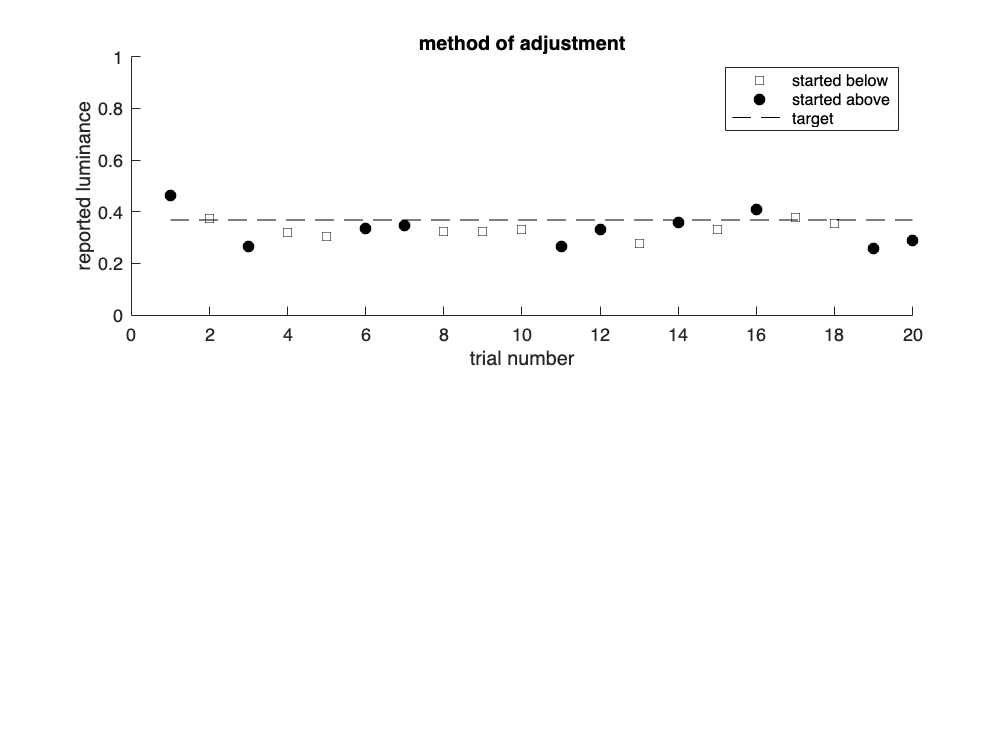

% the variable luminance_response contains the resoponse
luminance_response = adjust_data.luminance_response;

% the variable luminance_target contains the target luminance for each trial.  
% But there was only one for the whole experiment.
luminance_target = adjust_data.luminance_target;

% the variable control indicates where the controller started, at white (1)
% or background gray (-1)
control_start = adjust_data.control;
trials = 1:size(adjust_data,1);

figure(2); clf; 
subplot(211); hold on;


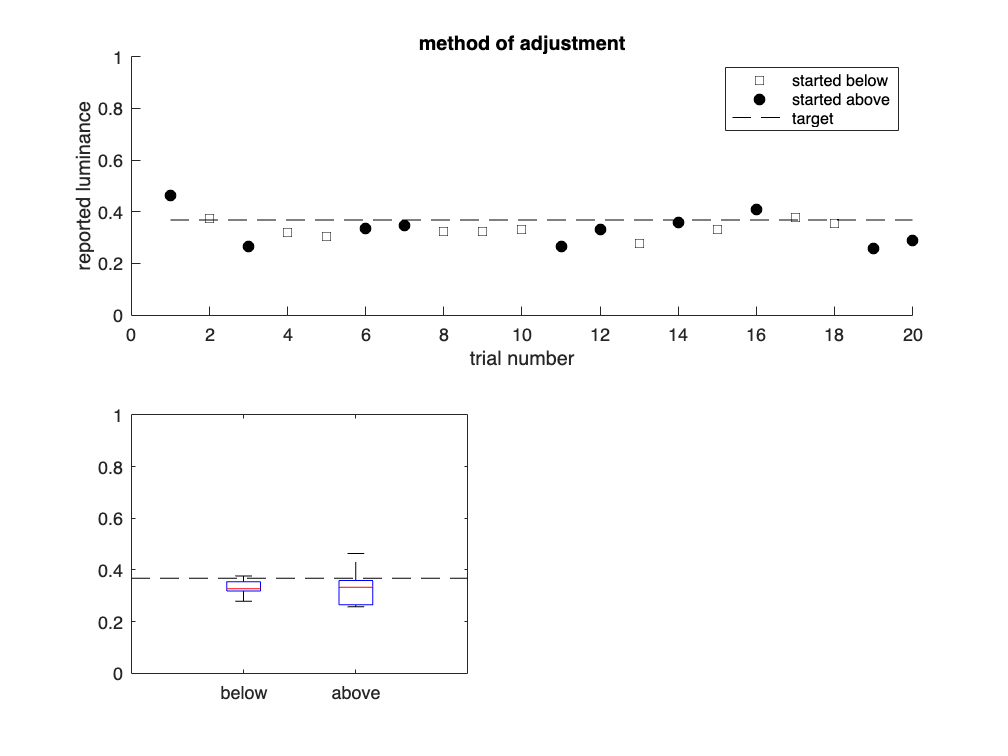

% plot the trials where the response started below
ind = control_start==-1;
plot(trials(ind),luminance_response(ind),'ks')

% plot the trials where the response started below
ind = control_start==1;
plot(trials(ind),luminance_response(ind),'ko','MarkerFaceColor','k')
plot(trials,luminance_target,'k--')

legend('started below','started above','target');
xlabel('trial number');
ylabel('reported luminance');
ylim([0,1]);
title('method of adjustment')

## Plot the average reported luminance separated by starting point

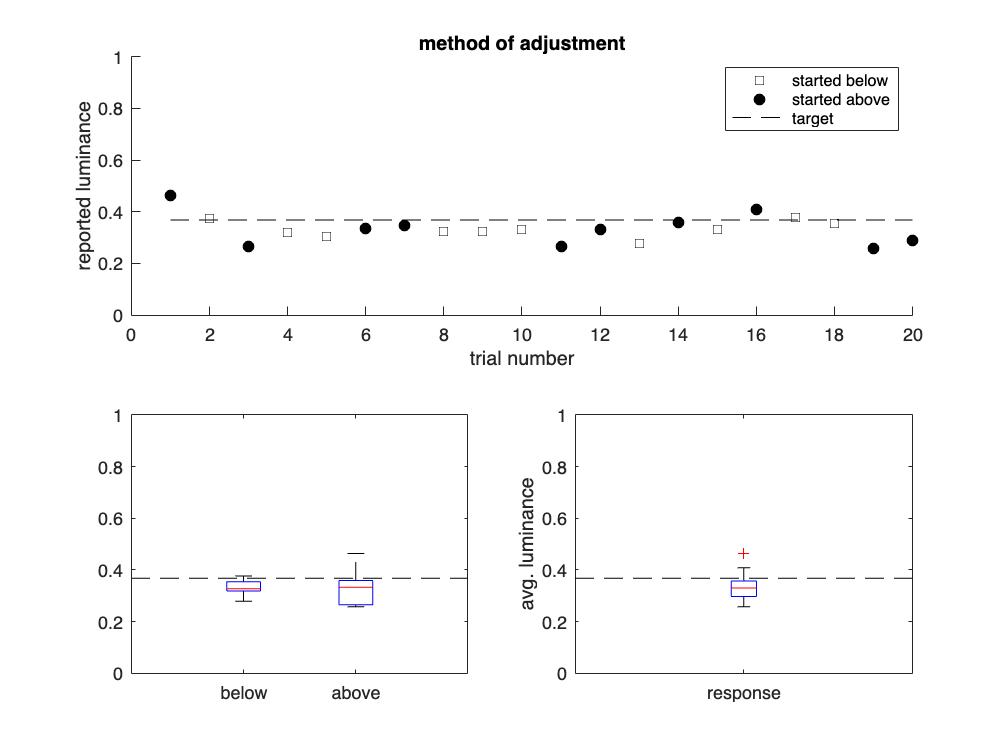

subplot(223); hold on;

boxplot(luminance_response,control_start)
xlim([0,3])

plot([0,3],mean(luminance_target)*[1,1],'k--')
set(gca,'XTickLabel',{'below','above'})

## Plot the average reported luminance

subplot(224); hold on;
boxplot(luminance_response)
xlim([0,2])
ylabel('avg. luminance');
set(gca,'XTickLabel',{'response'})
plot([0,2],mean(luminance_target)*[1,1],'k--')

## C. METHOD OF CONSTANT STIMULI

Instructions: First you will need to collect data. The folder titled "method-of-constant-stimuli" contains a .psyexp file that you will open using psychopy. Run the experiment -- there are instructions on the first panel for how to do each trial. Use the data generated in that experiment to do the analysis below.

## Load the data

% change the filename to the one you generated during data collection
filename = 'method-of-constant-stimuli/data/demo_method_of_constant_stimuli_2025-01-06_16h02.30.014.csv';
constant_data = readtable(filename);
% remove the rows/columns associated with the instructions in psychopy
constant_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
constant_data(:,remove) = [];

## Visualize the trials

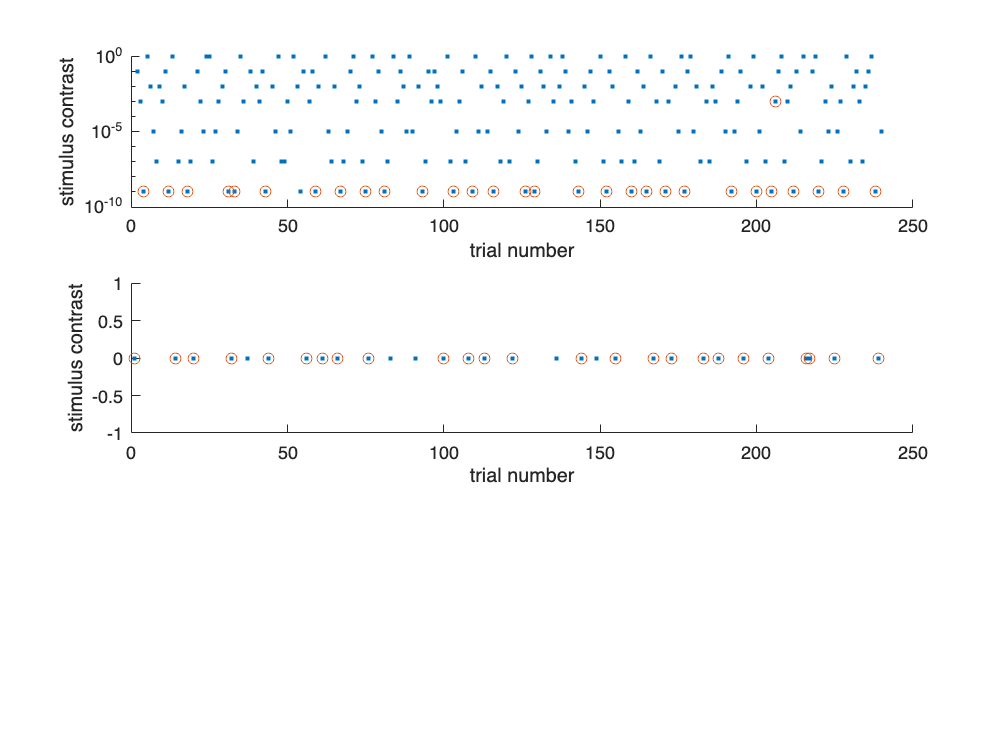

stimulus_contrast = constant_data.contrast;
response_key = constant_data.response_keys;
trials = 1:size(constant_data,1);

% convert the response_key to true for up and false for down.
response = strcmp(response_key,'up');

figure(3); clf;

% first plot the stimulus contrast on a log scale.  You should note that
% this will result in not plotting the trials that have zero contrast
% (which are 1/8th of the trials).
subplot(311); hold on;
plot(stimulus_contrast,'.');

% then plot a circle around the trials where the participant pressed down.
chose_down = response==false;
plot(trials(chose_down),stimulus_contrast(chose_down),'o')
xlabel('trial number');
ylabel('stimulus contrast')

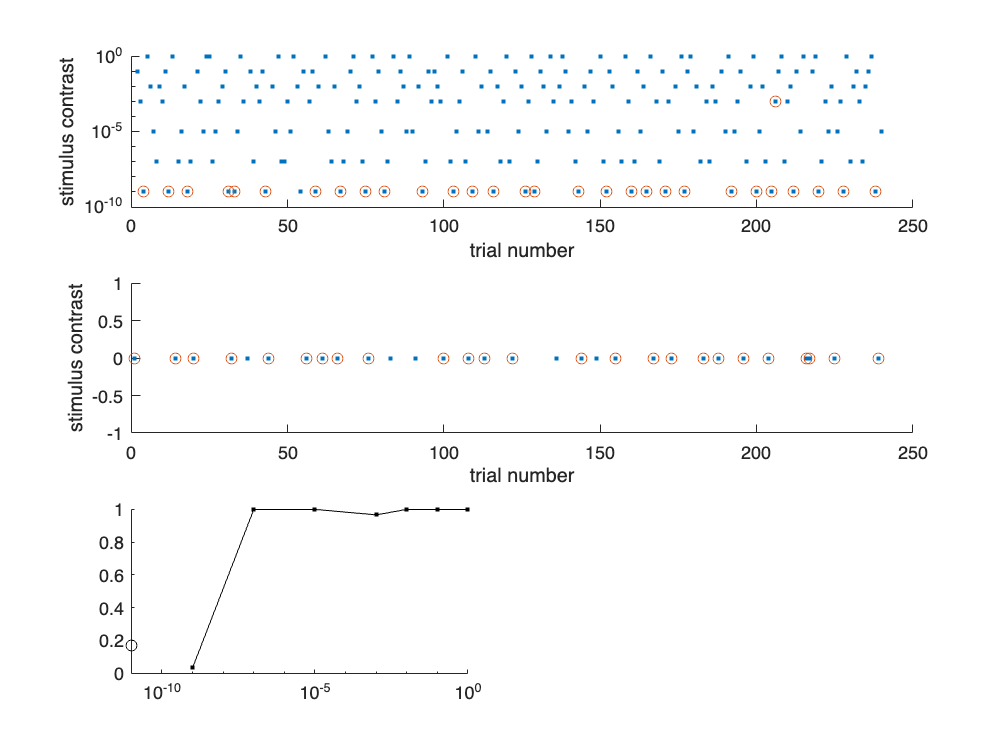

set(gca,'YScale','log')

% also plot the zero contrast trials
subplot(312); hold on;
was_zero = stimulus_contrast==0;
plot(trials(was_zero),stimulus_contrast(was_zero),'.');

% then plot a circle around the trials where the participant also pressed
% down.
ind = was_zero & chose_down;
plot(trials(ind),stimulus_contrast(ind),'o');
xlabel('trial number');

ylabel('stimulus contrast')

## Plot the percent reported present (up), as a function of contrast.

analysis_table = table;
analysis_table.Response = response;
analysis_table.Stimulus_Contrast = stimulus_contrast;
g = grpstats(analysis_table,'Stimulus_Contrast');

subplot(325); hold on;
plot(g.Stimulus_Contrast,g.mean_Response,'k.-');
% also plot the zero contrast (blank) trials
plot(1e-11,g.mean_Response(1),'ko')
set(gca,'XScale','log');